## synth_seismic_generator.mlx

This file was used to generate synthetic 30 second test cases by changing the number of wavefronts, their frequencies, attenuation factors, randomizing their amplitudes, etc.

Each output file was manually placed in the synth_output folder manually because we wanted to visually inspect the outputs before officially making them part of our synthetic test base for reasonableness.

The output files are in `.mat` and `.json` format.

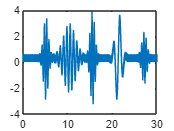

% Unless stated otherwise, time is in (s)
% Parameters
T = 30; % length of seismic recording
N = 5; % number of wavefronts
time_steps = 5000*30;

min_freq = 3;
max_freq = 10; % max frequency of wavefront burst

min_amplitude = 0.5;
max_amplitude = 3;

min_attenuation = 0.1;
max_attenuation = 2;

spacing_uncertainty = 1;
min_spacing = 5;
last_wavefront_start = 0;

t = linspace(0, T, time_steps);
synthetic_data = 0;

% insert another wavefront more and more into the future
for i = 1:N
    ai = max_amplitude*rand(1) + min_amplitude;
    bi = max_attenuation*rand(1) + min_attenuation;
    ci = spacing_uncertainty*rand(1) + last_wavefront_start + min_spacing;
    last_wavefront_start = ci;
    di = max_freq*rand(1) + min_freq;
    synthetic_data = synthetic_data + ai.*exp(-bi.*(t-ci).^2).*sin(di.*t);
end

synthetic_data = synthetic_data + 0.6*rand(1,time_steps);

% plot output synthetic data
plot(t, synthetic_data)


data = [t; synthetic_data];

% Metadata
metadata.author = 'Arba Shkreli';
metadata.creation_date = datestr(now);
metadata.description = sprintf("Amplitude: %.2f - %.2f \n" + ...
                               "Attenuation: %.2f - %.2f \n" + ...
                               "Spacing: %.2f - %.2f \n" + ...
                               "Frequency: %.2f - %.2f \n", ...
                                min_amplitude, max_amplitude, ...
                                min_attenuation, max_attenuation, ...
                                min_spacing, min_spacing+spacing_uncertainty, ...
                                min_freq, max_freq);

fullData.data = data;
fullData.metadata = metadata;

% Encode the array to JSON
jsonString = jsonencode(fullData);

% Get the current folder
currentFolder = pwd;

% Find if there are other test files in the folder to number off from
filePattern = 'test\d+\.mat';

% Get a list of all files in the current folder
allFiles = dir(currentFolder);

% Initialize a counter for matching files
matchingFileCount = 0;

% Loop through the files and count only those that match the pattern
for i = 1:length(allFiles)
    if ~allFiles(i).isdir && ~isempty(regexp(allFiles(i).name, filePattern, 'once'))
        matchingFileCount = matchingFileCount + 1;
    end
end

% Save the JSON string to a file
jsonFilename = sprintf('test%i.json', matchingFileCount+1);
fid = fopen(jsonFilename, 'w');
fprintf(fid, '%s', jsonString);
fclose(fid);

% also save as MAT file for use in Simulink directly
matFilename = sprintf('test%i.mat', matchingFileCount+1);
save(matFilename, 'fullData');